# Representing Images in MATLAB

Images are stored as arrays of numbers and often include information known as meta-data. The exact meta-data depends on the file format and camera but typically includes the image capture device, device settings, and date. You just learned how to read images into MATLAB. In this reading you will learn how to import and view the meta-data.

Most cameras store pixel intensities as 8-bit unsigned integers, or `uint8`. This saves memory and usually does a good job reproducing the image. However, many scientific images use specialized detectors instead of cameras. The range of values recorded by these devices often does not align with standard data types for storing numbers. 

In this reading, you'll: 

- View a file's meta-data 

- View images that are not stored as 8-bit unsigned integers

## Accessing Meta-Data

An image file's meta-data can provide valuable information. Consider an experiment where a camera acquires images when triggered by an external event, such as motion. Accessing the timestamp from the meta-data enables you to identify the event's time or track events over time.

Start by loading an image of Boston, Massachusetts that is included in the course files. 

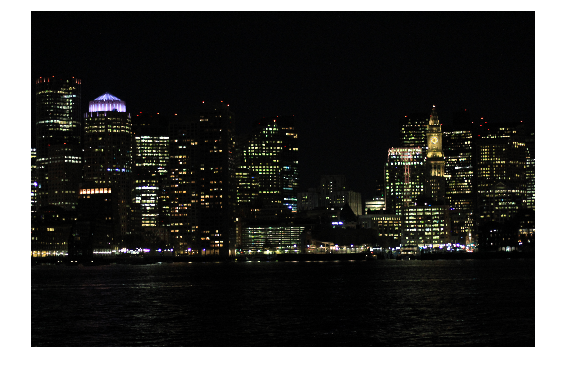

img = imread("/Users/anusha/Documents/MATLAB/Data/MathWorks Images/boston night.JPG");
imshow(img)

### View the meta-data

Load the meta-data using the `imfinfo` function. Pass the filename as input as the meta-data is stored in the file. Run this section to see what information is included with this image. You'll see a warning with this image and can ignore it as it's related to how the camera recorded some data.

metadata = imfinfo("/Users/anusha/Documents/MATLAB/Data/MathWorks Images/boston night.JPG")

metadata = struct with fields:
            Filename: '/Users/anusha/Documents/MATLAB/Data/MathWorks Images/boston night.JPG'
         FileModDate: '04-Jan-2022 16:37:38'
            FileSize: 4968075
              Format: 'jpg'
       FormatVersion: ''
               Width: 5184
              Height: 3456
            BitDepth: 24
           ColorType: 'truecolor'
     FormatSignature: ''
     NumberOfSamples: 3
        CodingMethod: 'Huffman'
       CodingProcess: 'Sequential'
             Comment: {}
                Make: 'Canon'
               Model: 'Canon EOS Rebel T6'
         Orientation: 1
         XResolution: 72
         YResolution: 72
      ResolutionUnit: 'Inch'
            DateTime: '2018:11:23 19:34:04'
              Artist: ''
    YCbCrPositioning: 'Co-sited'
           Copyright: ''
       DigitalCamera: [1×1 struct]
             GPSInfo: [1×1 struct]
       ExifThumbnail: [1×1 struct]


### Access individual pieces of meta-data

Lots of information is stored with this file, including the date and time, type of camera, and pixel resolution. Notice that the variable created is of data type `struct`. A `struct` is a single variable that stores a collection of mixed data in Fields. You access Fields using a dot after the variable name. This line of code accesses the `DateTime` Field of the structure variable `metadata`.

imgDate = metadata.DateTime

imgDate = '2018:11:23 19:34:04'

Some of the Fields are also of data type `struct.` An example is the Field `DigitalCamera`. Run this section to view the information about the camera. Notice that the variable `cameraInfo` is a structure variable, just like the `metadata` variable.

cameraInfo = metadata.DigitalCamera

cameraInfo = struct with fields:
                ExposureTime: 0.0167
                     FNumber: 1.8000
             ExposureProgram: 'Shutter priority'
             ISOSpeedRatings: 1600
                 ExifVersion: [48 50 51 48]
            DateTimeOriginal: '2018:11:23 19:34:04'
           DateTimeDigitized: '2018:11:23 19:34:04'
     ComponentsConfiguration: 'YCbCr'
           ShutterSpeedValue: 6
               ApertureValue: 1.6250
           ExposureBiasValue: 0
                MeteringMode: 'Pattern'
                       Flash: 'Flash did not fire, no strobe return detection function, compulsory flash suppression, flash function present, no red-eye reduction mode or unknown.'
                 FocalLength: 50
                   MakerNote: [37 0 1 0 3 0 49 0 0 0 80 5 0 0 2 0 3 0 4 0 0 0 178 5 0 0 3 0 3 0 4 0 0 0 186 5 0 0 4 0 3 0 34 0 0 0 194 5 0 0 6 0 2 0 19 0 0 0 6 6 0 0 7 0 2 0 24 0 0 0 38 6 0 0 9 0 2 0 32 0 0 0 62 6 0 0 13 0 7 0 0 6 0 0 94 6 0 0 16 0 4 … ]
             

#### Creating a datetime variable

Accessing timestamps of images is common, but notice that the `imgDate` variable you created is stored as a character array. If you work with timestamps, you need to convert this character array to a DATETIME variable. Do this with the `datetime `function. You need to specify the `InputFormat` that is used for the camera as shown below. You can determine the format used by inspecting the result above. There is lots you can do with datetime variables, like calculate durations and plot timeseries, however, these operations are beyond the scope of this course. View the [documentation for datetime](https://www.mathworks.com/help/matlab/ref/datetime.html#d123e299088) to learn more. 

Run this section to convert the character array `imgDate` to a datetime variable. Compare the results of `imgDate` and `imgDate2` in the workspace.

imgDate2 = datetime(imgDate, "InputFormat", "yyyy:MM:dd HH:mm:ss")

imgDate2 = datetime
   23-Nov-2018 19:34:04


## Viewing Non-UINT8 Images

Many engineering and scientific images use specialized detection methods. Examples include RADAR images and medical images like MRI. There are wide variations in how the data is recorded and stored, even within specific domains. Images may have only positive values or positive and negative values. The sensors may record a small or large range of values (known as the bit-depth). 

Regardless of the data type and range of values, you can still analyze your data using the techniques in this specialization. Let's see how to view these images.

### Load an MRI image

Included in the course files is a mat-file that contains a variable named `brainMRI`. Load the variable and view the image.

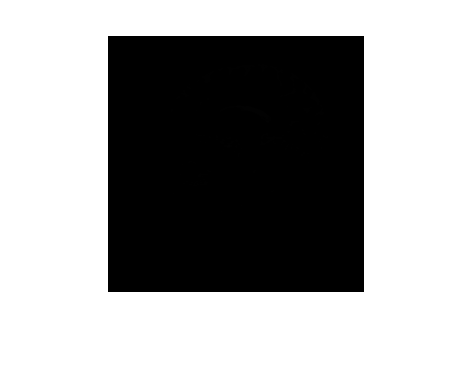

load brainMRI
imshow(brainMRI)

### Why is the image dark?

Notice that the data type of the variable is `uint16`. This is similar to `uint8`, but can store a much larger range of values:

- `uint8`: 0 - 255

- `uint16`: 0 - 65535

Thus, the intensity value must be 65535 to have a maximally bright pixel for this image. Run the code below to view the maximum value in the image and see the distribution of values.

max(brainMRI(:))

ans = uint16
725

The max value is much less than 65535, so all the pixels appear dark. However, because the maximum value is greater than 255, the data type `uint16` must be used to store the full range of values. 

#### Memory usage

The `uint8` and `uint16` data types are similar and you'll learn more about the limitations of integer data types later. The main difference you need to be aware of is that `uint16` stores a larger range of values and that `uint16`** images require twice the memory of **`uint8 `**images**. It is still more memory efficient to use `uint16` over `double`. 

- `uint8` images require 1 byte of memory for every pixel  

- `uint16` images require 2 bytes of memory

- `double` images require 8 bytes of memory

### Use a display range with IMSHOW

To view images like this MRI, use a second input with the IMSHOW function. You can automatically use the minimum and maximum values in the image or specify a custom range.

Use the minimum and maximum intensity values in the image by adding empty brackets as a 2nd input to the `imshow` function. 

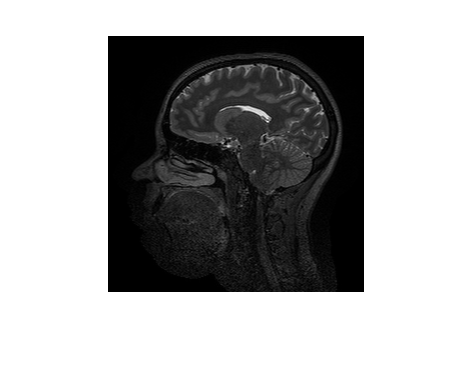

imshow(brainMRI, [])

It's common to compare images or focus on a specific intensity range in the image. In those types of applications, manually specifying an upper and lower value is more appropriate. Run this section to see MRI image. What differences do you notice between the two different display ranges?

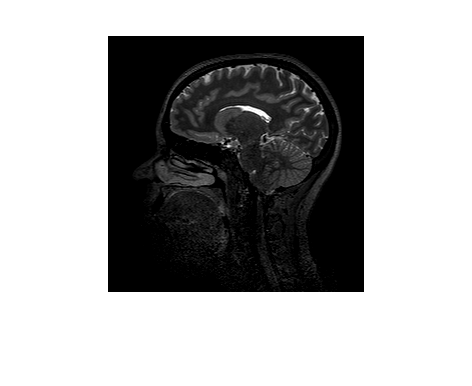

imshow(brainMRI, [50, 600])

#### Adding a colorbar

Knowing the actual intensity range is often important in these applications. Add a colorbar to the image to help you map the intensity display to the recorded numbers. 

Click on one of the images above. The toolstrip will update to include Figure tab. Select the Colorbar icon to add a colorbar to the image.

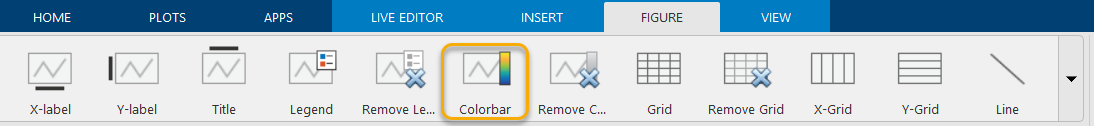

## Try Your Own Images

What meta-data is included with your images? Try reading in some of your photos and see what information is available. 

*Copyright 2022 The MathWorks, Inc.*

### **Try Your Own Images: **

Using blueberry image given in the dataset

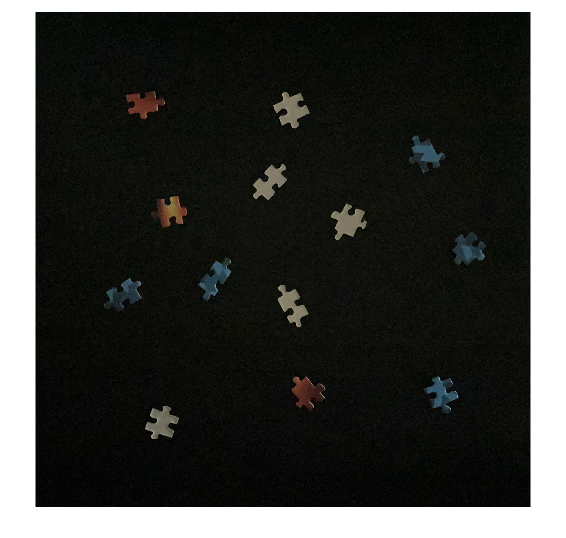

img = imread("/Users/anusha/Documents/MATLAB/Data/MathWorks Images/PuzzleBadLighting.jpg");
imshow(img)

After the images is displayed checking the max intensity :

max(img(:))

ans = uint8
200

Since its 255 pixels we can use uint8

imshow(img,[20,50])